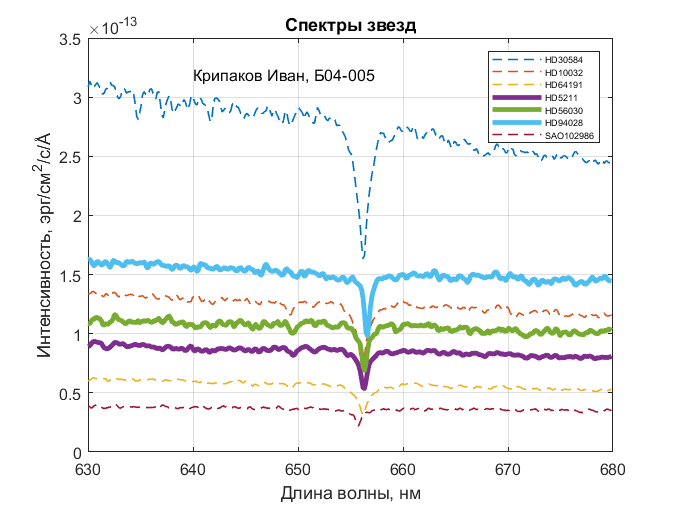

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
lambdaPr = 656.28;
speedOfLight = 299792.458;

nObs = size(spectra, 1);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

nStars = size(starNames, 1);
minInt = (1:nStars)';
idx = (1:nStars)';
lambdaHa = (1:nStars)';
speed = (1:nStars)';
fg1 = figure; 
for count = 1 : nStars
    [minInt(count, 1), idx(count, 1)] = min(spectra(:, count));
    lambdaHa(count, 1) = lambda(idx(count, 1));
    speed(count,1) = ((lambdaHa(count, 1) / lambdaPr) - 1) * speedOfLight;
end
for count = 1:count
    if speed(count, 1) > 0
        plot(lambda, spectra(:, count), 'LineWidth', 3)
    else
        plot(lambda, spectra(:, count), '--', 'LineWidth', 1)
    end
    hold on
end 

set(fg1, 'Visible',  'on');
grid on;
xlabel('Длина волны, нм');
ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
title('Спектры звезд');
legend(starNames, 'FontSize', 5.6);
text(lambdaStart + 10, max(spectra(:,1))*1.02, 'Крипаков Иван, Б04-005');
saveas(fg1, 'spectra.png');


B = speed > 0;
movaway = starNames(B)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}
